# **FALCIPARUM**

clear all
close all

I = imread("20171023_110309.jpg");
[alto, ancho] = size(I)

alto = 3024

ancho = 12096

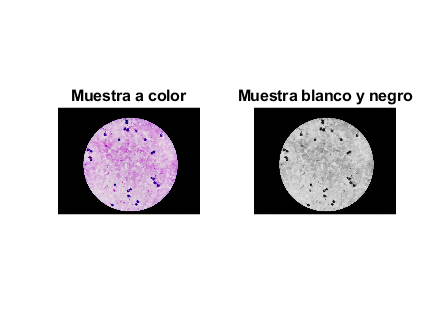

I_double = im2double(I);
subplot(1,2,1);imshow(I);title('Muestra a color');

I_gris = rgb2gray(I);
subplot(1,2,2);imshow(I_gris);title('Muestra blanco y negro');

I_gris_double = im2double(I_gris);

**1. FILTRAR EL RUIDO**

figure;
subplot(2, 3, 1); imshow(I_double);
title('Original');

Mediana

Elimina el ruido *Salt and Pepper*.

% R = medfilt2(I_double(:,:,1), [3 3]);
% G = medfilt2(I_double(:,:,2), [3 3]);
% B = medfilt2(I_double(:,:,3), [3 3]);
% 
% I_Mediana = cat(3, R, G, B);
% %I_Mediana_double = im2double(I_Mediana);
% 
% subplot(2,3,2);
% imshow(I_Mediana);
% title('Mediana');

Gaussiano

Elimina el ruido *Gauss*.

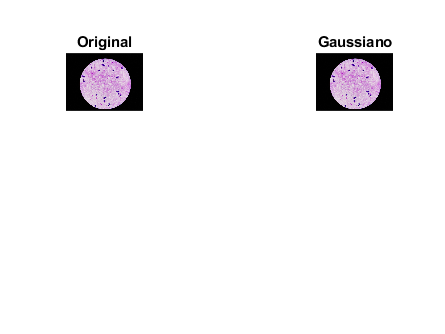

I_Gauss = imgaussfilt(I_double);
I_Gauss_double = im2double(I_Gauss);
subplot(2, 3, 3);imshow(I_Gauss);
title('Gaussiano');

Filtro de pase bajo basado en la media

% Filtro_Pase_Bajo = (1/9)*[1 1 1; 1 1 1; 1 1 1]; %%% (1/9) * ones(3,3);
% I_Pase_Bajo = imfilter(I_double, Filtro_Pase_Bajo);
% %I_Pase_Bajo_double = im2double(I_Pase_Bajo);
% subplot(2, 3, 4);imshow(I_Pase_Bajo); 
% title('Pase bajo');

Filtro de pase bajo basado en la media ponderada

% Filtro_Ponderado = (1/16) * [1 2 1; 2 4 2; 1 2 1];
% I_Ponderada = imfilter(I_double, Filtro_Ponderado);
% %I_Ponderada_double = im2double(I_Ponderada);
% subplot(2, 3, 5);imshow(I_Ponderada); 
% title('Ponderado');

Weiner

% R = wiener2(I_double(:,:,1), [5 5]);
% G = wiener2(I_double(:,:,2), [5 5]);
% B = wiener2(I_double(:,:,3), [5 5]);
% 
% I_Weiner = cat(3, R, G, B);
% %I_Weiner_double = im2double(I_Weiner);
% 
% subplot(2,3,6);
% imshow(I_Weiner);  % Convertir de nuevo a uint8 si es necesario
% title('Wiener');

Comparar el error de cada imagen

El MSE (Error Cuadrático Medio) ayuda a determinar qué filtro conserva mejor la información original de la imagen. Cuanto menor sea el MSE, menos distorsión.

% MSE_Mediana = immse(I_double,I_Mediana)
% MSE_Gaussiano = immse(I_double,I_Gauss)
% MSE_Pase_Bajo = immse(I_double,I_Pase_Bajo)
% MSE_Ponderado = immse(I_double,I_Ponderada)
% MSE_Weiner = immse(I_double,I_Weiner)

[alto_Gauss, ancho_Gauss] = size(I_Gauss)

alto_Gauss = 3024

ancho_Gauss = 12096

Como el valor más pequeño es el Gaussiano, nos quedaremos con ese filtro. 

De menor a mayor: **Gauss** < Ponderado < Mediana < Pase Bajo < Weiner

**2. EXTRAER ESTRUCTURAS CELULARES (TINCIÓN GIEMSA)**

- Núcleos --> azul 

- Citoplasma --> rosa (canal **G**reen y **R**ed)

- Fondo (residual) --> eliminamos

Queremos eliminar el fondo para quedarnos con el citoplasma y los núcleos.

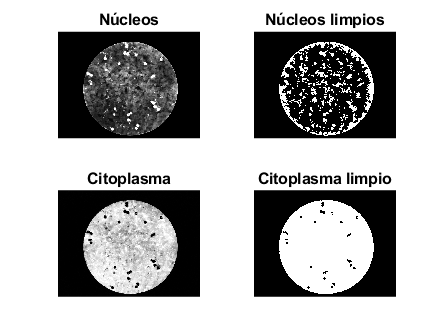

R = I_Gauss(:,:,1);  
G = I_Gauss(:,:,2);  
B = I_Gauss(:,:,3);  

% Núcleos
Nucleos = 2*B - R - G;  % Enfatiza azul 
Nucleos = imadjust(Nucleos); 
Nucleos_Binario = imbinarize(Nucleos, 'adaptive','Sensitivity', 0.3); % adaptive porque calcula umbrales locales para cada región de la imagen

% Citoplasma 
Citoplasma = (R + 0.7*G) - 0.8*B;
Citoplasma = imadjust(Citoplasma); 
Citoplasma_Binario = imbinarize(Citoplasma, 0.08); % 0.15 porque filtra el fondo y se queda con las zonas rosas claras

% Limpiamos
Nucleos_Limpios = imopen(Nucleos_Binario, strel('disk', 2));
Nucleos_Limpios_resized = imresize(Nucleos_Limpios, [alto, ancho]);
Citoplasma_Limpios = imclose(Citoplasma_Binario, strel('disk', 2));
Citoplasma_Limpios_resized = imresize(Citoplasma_Limpios, [alto, ancho]);
[alto_limpios, ancho_limpios] = size(Nucleos_Limpios);
[alto_limpios, ancho_limpios] = size(Citoplasma_Limpios);

figure;
subplot(2,2,1); imshow(Nucleos); title('Núcleos'); % Zonas azules resaltadas en escala de grises
subplot(2,2,2); imshow(Nucleos_Limpios); title('Núcleos limpios'); % máscara que limpia los núcleos --> lo bueno
subplot(2,2,3); imshow(Citoplasma); title('Citoplasma'); % Zonas rosas resaltadas en escala de grises
subplot(2,2,4); imshow(Citoplasma_Limpios); title('Citoplasma limpio'); % máscara que limpia el citoplasma --> lo bueno

**COORDENADAS REALES**

[alto, ancho] = size(I_Gauss)

alto = 3024

ancho = 12096

lines = readlines("20171023_110309.txt");
% Tabla 1
lines1 = lines(1);
dims = str2double(split(lines1, ','));
table_dims = array2table(dims')

table_dims = 1×3 table
    Var1    Var2    Var3
    ____    ____    ____

     31     4032    3024


% Tabla 2 
parasite_lines = lines(contains(lines, 'Parasite'));
parasite_data = cell(length(parasite_lines), 9);
for i = 1:length(parasite_lines)
    parts = strsplit(parasite_lines{i}, ',');
    parasite_data(i,:) = parts(1:9);
end
parasite_table = cell2table(parasite_data)

parasite_table = 6×9 table
    parasite_data1    parasite_data2    parasite_data3    parasite_data4    parasite_data5    parasite_data6    parasite_data7    parasite_data8    parasite_data9
    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________

       {'0-1' }        {'Parasite'}     {'No_Comment'}      {'Circle'}          {'2'}          {'2675.35'}        {'566'   }       {'2678'   }        {'579.25'}  
       {'0-2' }        {'Parasite'}     {'No_Comment'}      {'Circle'}          {'2'}          {'2271.25'}        {'544.95'}       {'2260.65'}        {'555.55'}  
       {'0-3' 

% Tabla 3
wbc_lines = lines(contains(lines, 'White_Blood_Cell'));
wbc_data = cell(length(wbc_lines), 7);
for i = 1:length(wbc_lines)
    parts = strsplit(wbc_lines{i}, ',');
    wbc_data(i,:) = parts(1:7);
end
wbc_table = cell2table(wbc_data)

wbc_table = 25×7 table
    wbc_data1         wbc_data2            wbc_data3       wbc_data4    wbc_data5     wbc_data6      wbc_data7 
    _________    ____________________    ______________    _________    _________    ___________    ___________

    {'0-10'}     {'White_Blood_Cell'}    {'No_Comment'}    {'Point'}      {'1'}      {'2226.95'}    {'664.7'  }
    {'0-11'}     {'White_Blood_Cell'}    {'No_Comment'}    {'Point'}      {'1'}      {'1972.9' }    {'613.9'  }
    {'0-12'}     {'White_Blood_Cell'}    {'No_Comment'}    {'Point'}      {'1'}      {'1953.85'}    {'372.6'  }
    {'0-13'}     {'White_Blood_Cell'}    {'No_Comment'}    {'Point'}      {'1'}      {'1941.15'}    {'436.1'  }
    {'0-14'}     {'White_Blood_Cell'}    {'No_Comment'}    {'Point

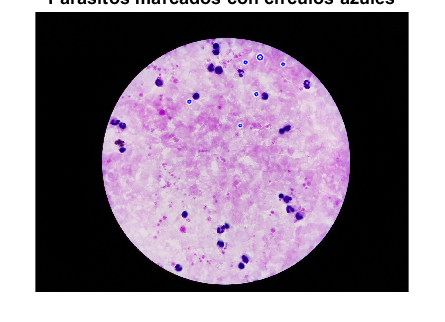


% Parasitos marcados
figure;
imshow(I_Gauss);
hold on;
x_centers = str2double(parasite_data(:,6));
y_centers = str2double(parasite_data(:,7));
x_perim = str2double(parasite_data(:,8));
y_perim = str2double(parasite_data(:,9));
radios = sqrt((x_perim - x_centers).^2 + (y_perim - y_centers).^2);
for i = 1:length(x_centers)
    % Dibujar círculo con centro (x_centers(i), y_centers(i)) y radio radios(i)
    viscircles([x_centers(i), y_centers(i)], radios(i), 'Color', 'blue', 'LineWidth', 1);
    
    % Opcional: marcar el centro con un punto
    %plot(x_centers(i), y_centers(i), 'b+', 'MarkerSize', 10, 'LineWidth', 2);
    
    % Opcional: marcar el punto del perímetro
    %plot(x_perim(i), y_perim(i), 'bo', 'MarkerSize', 8, 'LineWidth', 1);
end
hold off;
title('Parásitos marcados con círculos azules');

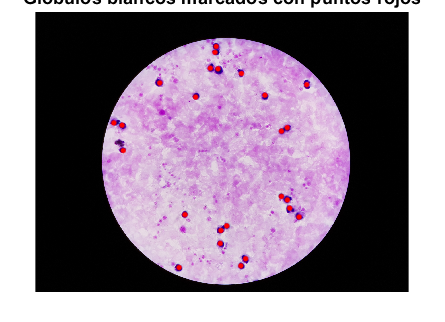

% White Blood Cells marcados
figure;
imshow(I_Gauss);
hold on; 
x_coords = str2double(wbc_table{:,6});
y_coords = str2double(wbc_table{:,7});
plot(x_coords, y_coords, 'r.', 'MarkerSize', 10);
hold off;
title('Glóbulos blancos marcados con puntos rojos');

**3. SEGMENTAR LAS IMÁGENES (4 MÉTODOS)**

Separación de tinción (Color Deconvolution) 

Giemsa usa azul y rosa para tintar. Este método separa estos colores en sus componentes puros.

Codigo con la matriz de tincion:

% % Densidad óptica
% OD = -log(I_Gauss_double + eps);
% 
% stain_matrix = [ ...
%     0.6220 0.0669 0.7071  % R
%     0.6741 0.9198 0.7071  % G
%     0.2738 0.1087 0.000]; % B
% stain_matrix = stain_matrix'; % Para que las columnas sean vectores
% 
% % Deconvolución
% stains = reshape(OD, [], 3) * inv(stain_matrix);
% stains = reshape(stains, size(I_Gauss_double));
% 
% % Canales de tinción
% nucleos_stain = stains(:,:,1);        % Canal 1 --> núcleos
% citoplasma_stain = stains(:,:,2);     % Canal 2 --> citoplasma
% 
% figure;
% nuc_norm = mat2gray(nucleos_stain);
% histogram(nuc_norm(:), 100, 'BinLimits', [0 1]);
% xlabel('Intensidad de tinción');
% ylabel('Frecuencia');
% title('Histograma RGB (normalizado)');
% 
% % Para que sea del mismo tamaño que la imagen original
% nucleos_stain_resized = imresize(nucleos_stain, [alto, ancho]);
% citoplasma_stain_resized = imresize(citoplasma_stain, [alto, ancho]);
% [alto_nucleos, ancho_nucleos] = size(nucleos_stain_resized)
% [alto_citoplasma, ancho_citoplasma] = size(nucleos_stain_resized)
% 
% % Resultados
% figure; 
% imshow(nucleos_stain,[], 'InitialMagnification', 'fit');
% colormap(gca, 'parula'); axis image off;
% title('Núcleos');
% 
% figure; 
% imshow(citoplasma_stain,[], 'InitialMagnification', 'fit');
% colormap(gca, 'hot'); axis image off;
% title('Citoplasma');
% 
% % Coordenadas de objetos segmentados
% %%% Glóbulos blancos
% stats_nucleos = regionprops(Nucleos_Limpios, 'Area', 'BoundingBox','Centroid','Eccentricity','PixelIdxList');
% min_area = 2000;
% max_area = 30000; 
% max_eccentricity = 0.9; % cerca de 0 es más circular y cerca de 1 más alargado
% min_stain_intensity = 0.4; 
% mean_intensity = zeros(length(stats_nucleos),1);
% for k = 1:length(stats_nucleos)
%     pixels = stats_nucleos(k).PixelIdxList;
%     mean_intensity(k) = mean(nucleos_stain(pixels));
% end
% disp('Intensidades medias:');
% disp(mean_intensity');
% leukocytes_nucleos = stats_nucleos( ...
%     [stats_nucleos.Area] > min_area & ...
%     [stats_nucleos.Area] < max_area & ...
%     [stats_nucleos.Eccentricity] < max_eccentricity & ...
%     mean_intensity' < min_stain_intensity ...
% ); % combinamos área (área max y min), forma y que tenga el color azul más intenso de todos
% figure;
% imshow(I_Gauss);hold on;
% for k = 1:length(leukocytes_nucleos)
%     rectangle('Position', leukocytes_nucleos(k).BoundingBox, 'EdgeColor', 'g', 'LineWidth', 2);
% end
% hold off;
% num_leucocitos = length(leukocytes_nucleos)

% %%% Parásitos (metodo como en los globulos blancos)
% % Eliminar los glóbulos blancos del citoplasma
% mask_leucocitos = false(size(Nucleos_Limpios));
% for k = 1:length(leukocytes_nucleos)
%     mask_leucocitos(leukocytes_nucleos(k).PixelIdxList) = true;
% end
% % Dilatar la máscara para cubrir todo el glóbulo blanco
% mask_leucocitos_dilated = imdilate(mask_leucocitos, strel('disk', 15));
% % Volver a limpiar el citoplasma
% Citoplasma_Limpios_sin_leucocitos = Citoplasma_Limpios & ~mask_leucocitos_dilated;
% % Buscar parásitos en las zonas de glóbulos blancos
% stats_todos_nucleos = regionprops(Nucleos_Limpios, 'Area', 'BoundingBox', 'Centroid', 'Eccentricity', 'PixelIdxList');
% min_area_parasito = 10;  
% max_area_parasito = 2000; 
% min_stain_intensity_parasito = 0.05; 
% max_stain_intensity_parasito = 1; 
% max_eccentricity_parasito = 0.7;
% mean_intensity_all = zeros(length(stats_todos_nucleos),1);
% for k = 1:length(stats_todos_nucleos)
%     pixels = stats_todos_nucleos(k).PixelIdxList;
%     mean_intensity_all(k) = mean(nucleos_stain(pixels));
% end
% idx_candidatos = find( ...
%     [stats_todos_nucleos.Area] > min_area_parasito & ...
%     [stats_todos_nucleos.Area] < max_area_parasito & ...
%     [stats_todos_nucleos.Eccentricity] < max_eccentricity_parasito & ...
%     mean_intensity_all' > min_stain_intensity_parasito & ...
%     mean_intensity_all' < max_stain_intensity_parasito);
% idx_leucocitos = find([stats_todos_nucleos.Area] > min_area);
% % Excluir los globulos blancos
% idx_parasitos = setdiff(idx_candidatos, idx_leucocitos);
% parasitos = stats_todos_nucleos(idx_parasitos);
% 
% figure;
% imshow(I_Gauss); 
% hold on
% for k = 1:length(parasitos)
%     %rectangle('Position', parasitos(k).BoundingBox,'EdgeColor', 'r', 'LineWidth', 1);
%     % Dibujar el centroide
%     plot(parasitos(k).Centroid(1), parasitos(k).Centroid(2), 'g.', 'MarkerSize', 5);
%     viscircles([x_centers(i), y_centers(i)], radios(i), 'Color', 'blue', 'LineWidth', 1);
% end
% num_parasitos = length(parasitos)
% 
% %Parasitos marcados
% x_centers = str2double(parasite_data(:,6));
% y_centers = str2double(parasite_data(:,7));
% x_perim = str2double(parasite_data(:,8));
% y_perim = str2double(parasite_data(:,9));
% radios = sqrt((x_perim - x_centers).^2 + (y_perim - y_centers).^2);
% for i = 1:length(x_centers)
%     % Dibujar círculo con centro (x_centers(i), y_centers(i)) y radio radios(i)
%     viscircles([x_centers(i), y_centers(i)], radios(i), 'Color', 'blue', 'LineWidth', 1);
% end
% hold off;
% %%% azul = real /// verde = estimado

Otsu (Umbralización global)

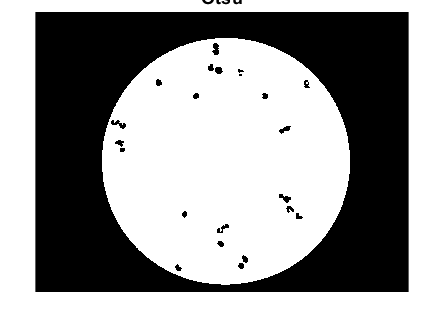

A = mean(im2double(I_Gauss), 3); % Promedia los 3 canales RGB --> transforma a grises
TO = graythresh(A); % Umbral óptimo de Otsu
C = A > TO; % Crear una imagen binaria: blanco si es mayor al umbral y negro si no
figure;
imshow(C);
title('Otsu'); 

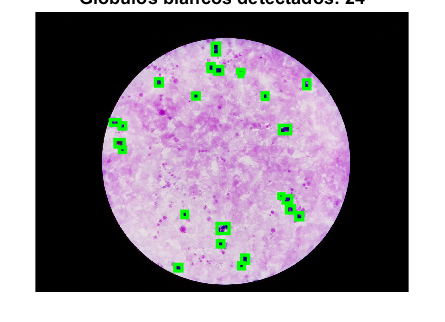


%%% Para contar las zonas negras (los glóbulos blancos)
BW_invert = ~C; % Invierte la imagen (blanco a negro y negro a blanco)
BW_clean = bwareaopen(BW_invert, 50); % Quita ruido pequeño (con menos de 50 pixeles)
[L, num] = bwlabel(BW_clean); % Etiqueta los objetos conectados = se identifican las zonas grandes

stats = regionprops(L, 'Area', 'Centroid', 'BoundingBox');
min_area = 100;
max_area = 30000;
mask_filtered = false(size(BW_clean));
for k = 1:num
    if stats(k).Area > min_area && stats(k).Area < max_area
        mask_filtered(L == k) = true;
    end
end % Nos quedamos con las formas que tienen un tamaño razoable = glóbulos blancos

[L_filtered, num_filtered] = bwlabel(mask_filtered);
stats_filtered_parasitos = regionprops(L_filtered, 'Area', 'Centroid', 'BoundingBox');
figure;
imshow(I_Gauss);
hold on;
for k = 1:num_filtered
    % Dibujar rectángulos alrededor de los glóbulos blancos detectados
    rectangle('Position', stats_filtered_parasitos(k).BoundingBox, 'EdgeColor', 'g', 'LineWidth', 2);
end
hold off;
title(['Glóbulos blancos detectados: ', num2str(num_filtered)]);

globulos_blancos = num2str(num_filtered) 

globulos_blancos = '24'

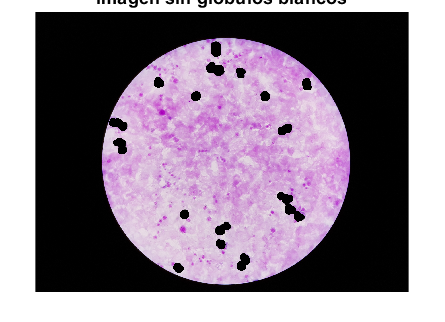


%%% Para contar parásitos
radio_dilatacion = 20;
se = strel('disk', radio_dilatacion);
mascara_dilatada = imdilate(mask_filtered, se);
% Hasta ahí hemos agrandado la zona porque a veces los glóbulos blancos tienen parásitos cerca
fondo_promedio = mean(mean(I_Gauss(1:10, :, :)));
I_Gauss_sin_globulos = I_Gauss;
for c = 1:3 % Aplicar a cada canal RGB
    canal = I_Gauss(:,:,c);
    canal(mascara_dilatada) = fondo_promedio(c); % Rellenar con color de fondo
    I_Gauss_sin_globulos(:,:,c) = canal;
end
figure;
figure; imshow(I_Gauss_sin_globulos); title('Imagen sin glóbulos blancos');

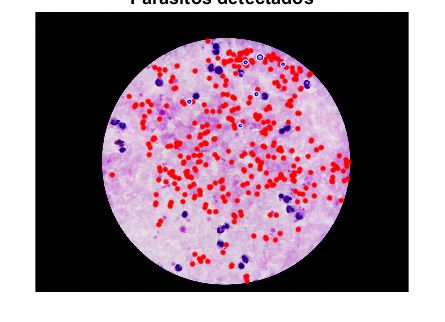


I_gray = rgb2gray(I_Gauss_sin_globulos);
I_contrast = adapthisteq(I_gray);
th = graythresh(I_contrast);
BW = imbinarize(I_contrast, th);
BW = imopen(~BW, strel('disk', 1));
BW_clean = bwareaopen(BW, 30); % Preparamos la imagen para detectar parásitos, resaltándolos y limpiando el ruido

[L, num] = bwlabel(BW_clean);
stats = regionprops(L, 'Area', 'BoundingBox','Centroid','EquivDiameter');
min_area_parasitos = 20;
max_area_parasitos = 1000;
mask_filtered_parasitos = false(size(BW_clean));
for k = 1:num
    if stats(k).Area > min_area_parasitos && stats(k).Area < max_area_parasitos
        mask_filtered_parasitos(L == k) = true;
    end
end

[L_filtered, num_filtered] = bwlabel(mask_filtered_parasitos);
stats_filtered = regionprops(L_filtered, 'BoundingBox','Centroid','EquivDiameter');
centros = cat(1, stats_filtered.Centroid);
radios = [stats_filtered.EquivDiameter] / 2;

figure;
imshow(I_Gauss);
hold on;

%viscircles(centros, radios', 'Color', 'r', 'LineWidth', 1);

plot(centros(:,1), centros(:,2),'r.','MarkerSize',10);
title(['Parasitos detectados']);

%Parasitos marcados
x_centers = str2double(parasite_data(:,6));
y_centers = str2double(parasite_data(:,7));
x_perim = str2double(parasite_data(:,8));
y_perim = str2double(parasite_data(:,9));
radios = sqrt((x_perim - x_centers).^2 + (y_perim - y_centers).^2);
for i = 1:length(x_centers)
    % Dibujar círculo con centro (x_centers(i), y_centers(i)) y radio radios(i)
    viscircles([x_centers(i), y_centers(i)], radios(i), 'Color', 'blue', 'LineWidth', 1);
end
hold off;

num_parasitos = length(stats_filtered)

num_parasitos = 345

%%% azul = real /// verde = estimado

**CONSEGUIR DATOS TABULARES:**

Una vez tenemos la información de cuántos glóbulos blancos y cuántos parásitos tenemos y dónde están ubicados, como tenemos ruido y falsos positivos en esas conclusiones, usaremos el ground truth (anotaciones) para sacar las características de dichas estructuras.

Glóbulos Blancos:

x_coords = str2double(wbc_table{:,6});
y_coords = str2double(wbc_table{:,7});

% Usamos la imagen original porque es de donde se han sacado las anotaciones

% Creamos ROI (Región de Interés --> una ventana)
ROI = 50; % IR AJUSTANDO!!!!!

Globulos_Blancos_Caracteristicas = table();
for i = 1:length(x_coords)
    x = round(x_coords(i));
    y = round(y_coords(i));

    % Definir ROI alrededor del punto
    x_min = max(x - ROI, 1); % queremos ir desde x - ROI pero si x está cerca del borde izk nos da negativo, asi que tiene que ser el maximo
    x_max = min(x + ROI, size(I,2));
    y_min = max(y - ROI, 1);
    y_max = min(y + ROI, size(I,1));

    % Extraer ROI de cada canal
    roi_rgb = I(y_min:y_max, x_min:x_max, :);
    roi_gray = I_gray(y_min:y_max, x_min:x_max); 

    % Umbralizar
    roi_bin = imbinarize(roi_gray, 'adaptive', 'Sensitivity', 0.4);
    roi_bin = imopen(roi_bin, strel('disk', 2));

    % Etiquetar componentes detectados
    [L_roi, ~] = bwlabel(roi_bin);
    stats = regionprops(L_roi, roi_gray, 'Area', 'Perimeter', 'Eccentricity', 'EquivDiameter', 'Solidity', 'MeanIntensity', 'BoundingBox', 'Circularity');
    
    % Dentro de ROI nos quedamos con el objeto más grande = globulo blanco
    if ~isempty(stats)
        [~, idx_max] = max([stats.Area]);
        s = stats(idx_max);

        % Guardar características en tabla
        Globulos_Blancos_Caracteristicas = [Globulos_Blancos_Caracteristicas; struct2table(s)]; % con struct2table(s) convertimos las propiedades del objeto (s) en una fila de la tabla
    end 
end
medianas_globulos = varfun(@median, Globulos_Blancos_Caracteristicas);
medianas_globulos.Num_Globulos = height(Globulos_Blancos_Caracteristicas);
medianas_globulos = movevars(medianas_globulos, 'Num_Globulos', 'Before', 1); % Para que sea la primera columna

display(medianas_globulos);

medianas_globulos = 1×9 table
    Num_Globulos    median_Area         median_BoundingBox         median_Eccentricity    median_Circularity    median_EquivDiameter    median_Solidity    median_Perimeter    median_MeanIntensity
    ____________    ___________    ____________________________    ___________________    __________________    ____________________    _______________    ________________    ____________________

         25             124        61.5    17.5      23      22          0.98748               0.35865                 12.565               0.81622             66.18                0.76645       


Parásitos:

x_centers = str2double(parasite_data(:,6));
y_centers = str2double(parasite_data(:,7));
x_perim = str2double(parasite_data(:,8));
y_perim = str2double(parasite_data(:,9));
radios = sqrt((x_perim - x_centers).^2 + (y_perim - y_centers).^2);

% Usamos la imagen original porque es de donde se han sacado las anotaciones

Parasitos_Caracteristicas = table();
for i = 1:length(x_centers)
    x = round(x_centers(i));
    y = round(y_centers(i));
    r = ceil(radios(i));

    % Definir ROI cuadrado que tenga el circulo dentro
    x_min = max(x - r, 1); % queremos ir desde x - ROI pero si x está cerca del borde izk nos da negativo, asi que tiene que ser el maximo
    x_max = min(x + r, size(I,2));
    y_min = max(y - r, 1);
    y_max = min(y + r, size(I,1));

    % Extraer ROI de cada canal
    roi_gray_parasitos = I_gray(y_min:y_max, x_min:x_max);

    % Máscara del tamaño de ROI
    [cols, rows] = meshgrid(x_min:x_max, y_min:y_max);
    mask = (cols - x).^2 + (rows - y).^2 <= r^2;

    % Umbralización dentro de la máscara
    roi_masked = roi_gray;
    roi_masked(~mask) = 0;  % Fuera del círculo = negro
    roi_bin = imbinarize(roi_masked, 'adaptive', 'Sensitivity', 0.4);
    roi_bin = imopen(roi_bin, strel('disk', 1));

    % Etiquetar componentes detectados
    L_roi = bwlabel(roi_bin);
    stats = regionprops(L_roi, roi_masked, 'Area', 'Perimeter', 'Eccentricity', 'EquivDiameter', 'Solidity', 'MeanIntensity', 'BoundingBox', 'Circularity');
    
    if ~isempty(stats)
        [~, idx_max] = max([stats.Area]);
        s = stats(idx_max);

        % Guardar características en tabla
        Parasitos_Caracteristicas = [Parasitos_Caracteristicas; struct2table(s)]; % con struct2table(s) convertimos las propiedades del objeto (s) en una fila de la tabla
    end 
end
medianas_parasitos = varfun(@median, Parasitos_Caracteristicas);
medianas_parasitos.Num_Parasitos = height(Parasitos_Caracteristicas);
medianas_parasitos = movevars(medianas_parasitos, 'Num_Parasitos', 'Before', 1); % Para que sea la primera columna

display(medianas_parasitos);

medianas_parasitos = 1×9 table
    Num_Parasitos    median_Area        median_BoundingBox        median_Eccentricity    median_Circularity    median_EquivDiameter    median_Solidity    median_Perimeter    median_MeanIntensity
    _____________    ___________    __________________________    ___________________    __________________    ____________________    _______________    ________________    ____________________

          6              426        11     0.5    90.5      39          0.96461               0.10427                 23.289               0.21195             226.03               0.75804       


Watershed

% mask = I_gris > 30; % Para eliminar el fondo negro
% mask = imfill(mask,'holes');
% mask = imerode(mask,strel('disk',5));
% 
% nucleos = 2*I_Gauss(:,:,3) - I_Gauss(:,:,1) - I_Gauss(:,:,2);
% nucleos = imgaussfilt(nucleos, 1.5);
% nucleos = imadjust(nucleos);
% nucleos(~mask) = 0;
% 
% citoplasma = (I_Gauss(:,:,1) + 0.7*I_Gauss(:,:,2)) - 0.8*I_Gauss(:,:,3);
% citoplasma = imgaussfilt(citoplasma, 1.5);
% citoplasma = imadjust(citoplasma);
% 
% %%% Glóbulos blancos
% bw_leuk = imbinarize(nucleos, 'adaptive', 'Sensitivity', 0.7);
% bw_leuk = imopen(bw_leuk, strel('disk', 3));
% bw_leuk = imclose(bw_leuk, strel('disk', 5));
% bw_leuk = bw_leuk & mask; % Aplicar la máscara
% bw_leuk = bwareaopen(bw_leuk, 2000); % Área mínima para ser glóbulo blanco
% 
% % Watershed 
% D = -bwdist(~bw_leuk);
% D = imhmin(D, 2); 
% L = watershed(D);
% bw_leuk = L > 1;  
% bw_leuk = imfill(bw_leuk, 'holes');
% bw_leuk = bwareaopen(bw_leuk, 2000);
% 
% stats_leuk = regionprops(L, 'Area', 'Centroid', 'BoundingBox', 'Eccentricity','PixelIdxList');
% min_area_leuk = 2000;
% max_area_leuk = 30000;
% max_eccentricity = 0.9;
% min_stain_intensity = 0.4; 
% mean_intensity = zeros(length(nucleos),1);
% leukocytes = [];
% for k = 1:length(stats_leuk)
%     area = stats_leuk(k).Area;
%     ecc = stats_leuk(k).Eccentricity;
%     stain_intensity = mean(nucleos(stats_leuk(k).PixelIdxList));  % intensidad media en la región
% 
%     if area >= min_area_leuk && ...
%        area <= max_area_leuk && ...
%        ecc <= max_eccentricity && ...
%        stain_intensity >= min_stain_intensity
% 
%         leukocytes = [leukocytes; stats_leuk(k)];
%     end
% end
% 
% figure;
% imshow(I_Gauss); hold on;
% for k = 1:length(leukocytes)
%     rectangle('Position', leukocytes(k).BoundingBox,'EdgeColor', 'g', 'LineWidth', 2);
% end
% 
% hold off;
% title('Globulos blancos');
% Globulos_bancos = num2str (length(leukocytes))

K-means

% img_size = size(I_double);
% nRows = img_size(1);
% nCols = img_size(2);
% 
% % Convertir a una lista de píxeles (cada fila es un pixel RGB)
% pixels = reshape(I_double, [], 3);  % nPixels x 3
% 
% % Número de clusters (ajústalo según lo que busques: 3 suele ser útil)
% nColors = 3;
% [cluster_idx, cluster_center] = kmeans(pixels, nColors, 'distance', 'sqEuclidean', 'Replicates', 3);
% 
% % Reconstruir imagen segmentada por clusters
% pixel_labels = reshape(cluster_idx, nRows, nCols);
% segmented_images = cell(1, nColors);
% rgb_label = repmat(pixel_labels, [1 1 3]);
% 
% for k = 1:nColors
%     color = I;
%     color(rgb_label ~= k) = 0;
%     segmented_images{k} = color;
% end
% 
% % Mostrar resultados
% figure;
% for k = 1:nColors
%     subplot(1,nColors,k);
%     imshow(segmented_images{k});
%     title(sprintf('Cluster %d', k));
% end
% 
% % Mostrar cada cluster con colores distintos
% figure;
% rgb_labels = label2rgb(pixel_labels);
% imshow(rgb_labels);
% title('K-means Clustering');

HSV:

% I_HSV = rgb2hsv(I_Gauss);
% H = I_HSV(:,:,1); % Matiz
% S = I_HSV(:,:,2); % Saturación
% V = I_HSV(:,:,3); % Valor
% 
% figure;
% subplot(1,3,1); imshow(H); title('Hue (H)');
% subplot(1,3,2); imshow(S); title('Saturation (S)');
% subplot(1,3,3); imshow(V); title('Value (V)');
% 
% %%% Glóbulos blancos
% WBC_mask = (H > 0.55) & (H < 0.75) & (S > 0.3) & (V > 0.2); % S > 0.3 para eliminar el fondo y V > 0.2 para ayudar a evitar zonas muy oscuras
% WBC_mask = imopen(WBC_mask, strel('disk', 2)); % Limpieza morfológica
% WBC_mask = imclose(WBC_mask, strel('disk', 4));
% WBC_mask = imfill(WBC_mask, 'holes');
% WBC_mask = bwareaopen(WBC_mask, 800);
% 
% figure;
% imshow(I_Gauss); hold on;
% WBC_props = regionprops(WBC_mask, 'BoundingBox', 'Centroid');
% for k = 1:length(WBC_props)
%     box = WBC_props(k).BoundingBox;
%     rectangle('Position', box, 'EdgeColor', 'g', 'LineWidth', 1.5); % Cuadro verde
% end
% hold off;
% title('Glóbulos blancos')
% Globulos_Blancos = num2str (length(WBC_props))
% 
% %%% Parásitos
% Parasite_mask = (H > 0.58) & (H < 0.75) & (S > 0.4) & (V > 0.1);
% Parasite_mask = imopen(Parasite_mask, strel('disk', 1));
% Parasite_mask = imclose(Parasite_mask, strel('disk', 2));
% Parasite_mask = bwareaopen(Parasite_mask, 20);